% Generate I and Q Baseband Data
numberOfBits = 1000;
bitsPerSymbol = 4;

numberOfSymbols = numberOfBits/bitsPerSymbol;

M = 2^bitsPerSymbol;

% % Generate Raw Bits
% bits = randi([0, 1],[1, numberOfBits]);
% 
% % Group into Symbols
% symbols = zeros([1, numberOfSymbols]);
% for k = 1:numberOfSymbols
%     idx = bitsPerSymbol*(k-1) + 1;
%     for n = 0:bitsPerSymbol-1
%         symbols(k) = symbols(k) + (2^n)*bits(k+n);    
%     end  
% end
% 
% symbolsBin = dec2bin(symbols);
% [symbolsGray, map] = bin2gray(symbols, 'qam', M)
% 

idxI = randi([1, bitsPerSymbol],[1, numberOfSymbols]);
idxQ = randi([1, bitsPerSymbol],[1, numberOfSymbols]);

numberOfLevels = bitsPerSymbol;
levels = 1:2:numberOfLevels-1;
levels = [-flip(levels), levels];
numberOfLevels = length(levels);

assert(numberOfLevels == bitsPerSymbol, 'Error: Number of Levels != Number of Bits/ Symbol')
A = 10;
symbolsI = zeros(size(idxI));
symbolsQ = zeros(size(idxQ));
for k = 1:length(idxI)
    symbolsI(k) = A*levels(idxI(k));
    symbolsQ(k) = A*levels(idxQ(k));
end
disp('Symbols Created')

Symbols Created


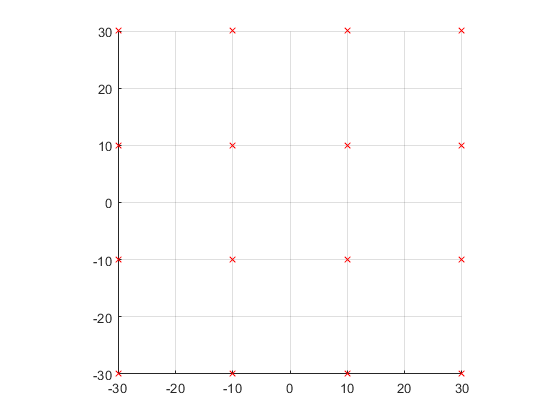

scatter(symbolsI, symbolsQ, 'xr')
grid on
axis square

% Signal Params
bitRate = 1;
symbolRate = bitRate/bitsPerSymbol;

carrierFrequency = 10;
samplesPerCycle = 2^7; % Needs to be power of 2
% samplesPerSymbol = samplesPerCycle*carrierFrequency/symbolRate;

Fs = samplesPerCycle*carrierFrequency;
Ts = 1/Fs;


% L = samplesPerCycle*numberOfSymbols*carrierFrequency/symbolRate;
L = numberOfSymbols*samplesPerCycle;
time = Ts*(0:L-1);
bitTime = 1/bitRate;
symbolTime = 1/symbolRate;
disp('Time Vectors Created')

Time Vectors Created


% Generate Upsampled Bits
zoh = ones([1 samplesPerCycle]);

symbolsUpsampledI = upsample(symbolsI, samplesPerCycle);
x_MPAM_I = convfft(symbolsUpsampledI, zoh);
x_MPAM_I = x_MPAM_I(1:L)';

symbolsUpsampledQ = upsample(symbolsQ, samplesPerCycle);
x_MPAM_Q = convfft(symbolsUpsampledQ, zoh);
x_MPAM_Q = x_MPAM_Q(1:L)';
disp('MPAM Data Created')

MPAM Data Created


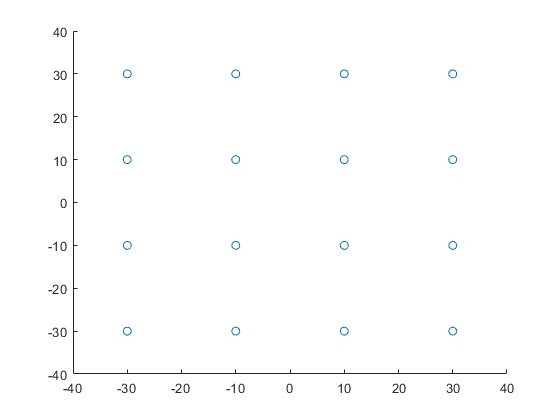


scatter(x_MPAM_I, x_MPAM_Q)

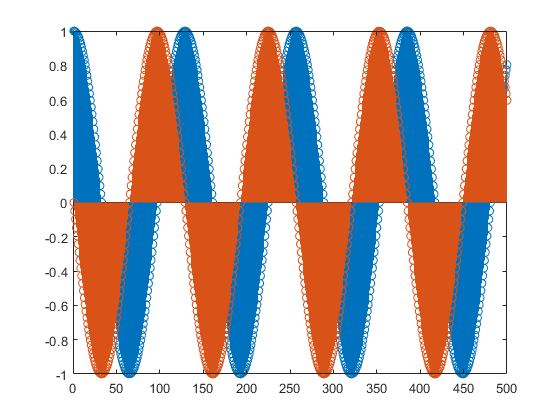

% Up Conversion LO
LO_I = 1*cos(2*pi*carrierFrequency*time);
LO_Q = -1*sin(2*pi*carrierFrequency*time);
% close all
stem(LO_I)
hold on
stem(LO_Q)
xlim([0, 0.005e5])



% scatter(x_MPAM_I_RF, x_MPAM_Q_RF)

% Up Convert to RF
x_QAM_I = LO_I.*x_MPAM_I;
x_QAM_Q = LO_Q.*x_MPAM_Q;

% PSD of I/Q RF Signal
hold off

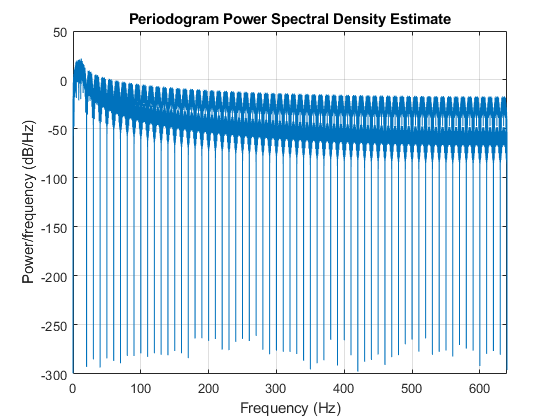

periodogram(x_QAM_I,rectwin(length(x_QAM_I)),length(x_QAM_I),Fs, 'onesided')
hold on
periodogram(x_QAM_Q,rectwin(length(x_QAM_Q)),length(x_QAM_Q),Fs, 'onesided')
hold off

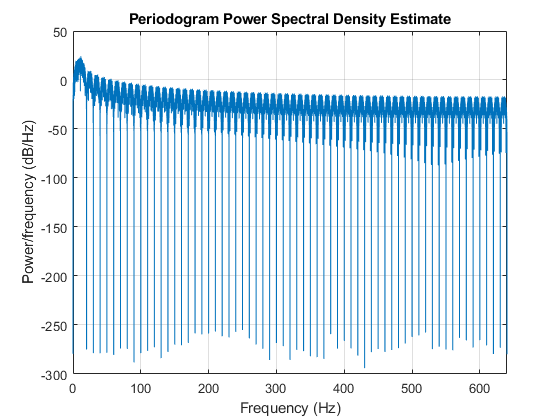

% Create the RF QAM Signal
x_QAM = x_QAM_I + x_QAM_Q;
% span = symbolRate;
% x_QAM_Filtered = bandpass(x_QAM, [carrierFrequency - span, carrierFrequency + span], Fs);
% disp('QAM Signal Created')

% PSD of QAM RF Signal
periodogram(x_QAM,rectwin(length(x_QAM)),length(x_QAM),Fs, 'onesided')

% periodogram(x_QAM_Filtered,rectwin(length(x_QAM_Filtered)),length(x_QAM_Filtered),FsRF, 'onesided')

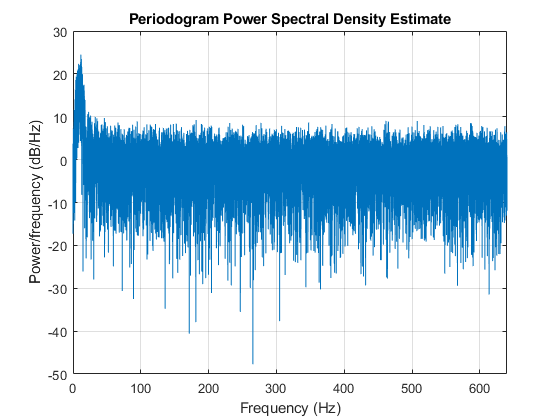

% Simulate Noisy Channel
% variance = 1/(Ts*(10^(SNRdB/10)));
digitalSNR = 10; %dB
digitalSNR = 10.^(digitalSNR/10);
variance = (A^2*samplesPerCycle)/(2*digitalSNR);
noise = sqrt(variance)*randn(size(time));

% Recieved Signal
sRX = x_QAM + noise;
periodogram(sRX,rectwin(length(sRX)),length(sRX),Fs, 'onesided')

% Calculate SNR -> Wrong?
% BW = obw(sRX, Fs);
% SNRa = var(x_QAM)/var(noise);
% SNRd = SNRa*BW/bitRate;
% disp('Noisy QAM Signal Created')
% fprintf('Analog SNR is %.2f dB\n', 10*log10(SNRa))
% fprintf('Digital SNR is %.2f dB\n', 10*log10(SNRd))
% fprintf('Signal Bandwidth is %.2f Hz\n', BW)

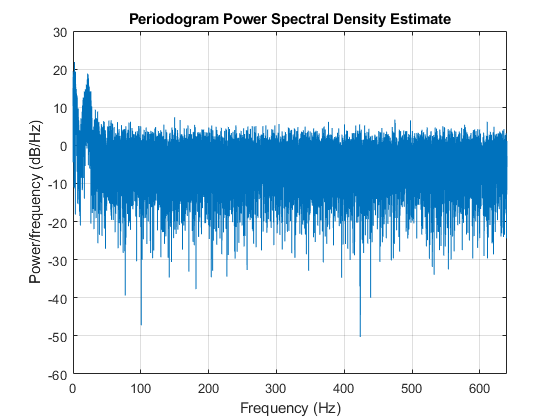

% Split Data into I and Q Channels
s_I = sRX.*LO_I;
s_Q = sRX.*LO_Q;
periodogram(s_I,rectwin(length(s_I)),length(s_I),Fs, 'onesided')

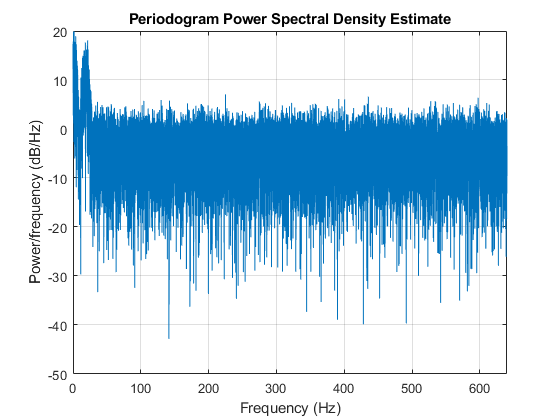

periodogram(s_Q,rectwin(length(s_Q)),length(s_Q),Fs, 'onesided')


% s_I3 = lowpass(s_I, carrierFrequency, Fs); 
% s_Q3 = lowpass(s_Q, carrierFrequency, Fs); 
% periodogram(s_I3,rectwin(length(s_I3)),length(s_I3),FsRF, 'onesided')
% periodogram(s_Q3,rectwin(length(s_Q3)),length(s_Q3),FsRF, 'onesided')
% scatter(s_I3, s_Q3)
disp('RX Downconvert Done')

RX Downconvert Done


mI = zeros([1, numberOfSymbols]);
mQ = zeros([1, numberOfSymbols]);
for k = 1:numberOfSymbols
    startIdx = (k-1)*samplesPerCycle+1;
    endIdx = k*samplesPerCycle;
    for w = startIdx:endIdx
        mI(k) = mI(k) + s_I(w);
        mQ(k) = mQ(k) + s_Q(w);           
    end
end
disp('RX Decimate Done')

RX Decimate Done


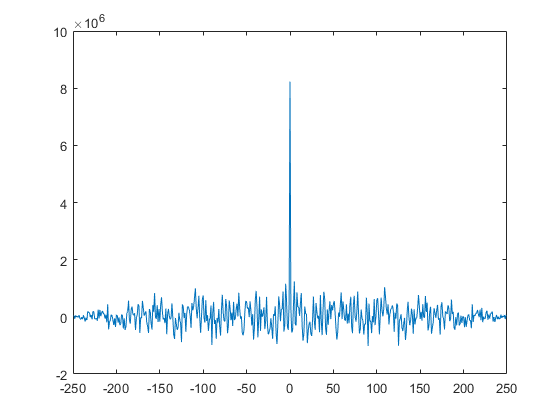

[RmI, tauI] = xcorr(symbolsI, mI);
plot(tauI, RmI)

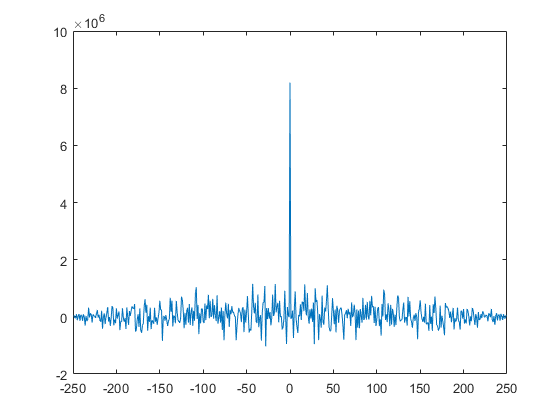

[RmQ, tauQ] = xcorr(symbolsQ, mQ);
plot(tauQ, RmQ)

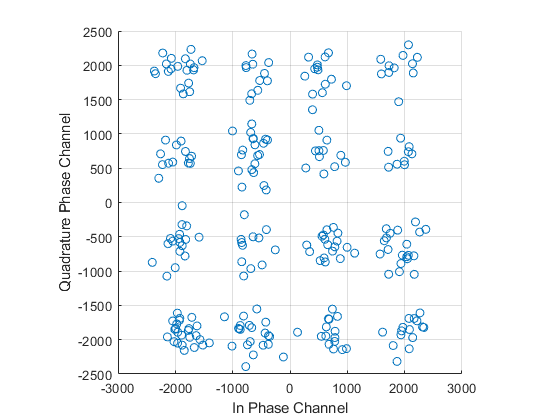

% Plot Signal Constellation
% close all
scatter(mI, mQ)
xlabel('In Phase Channel')
ylabel('Quadrature Phase Channel')
grid on
axis square

% Decode back into symbols
mI = mI/max(mI)*max(levels);
mQ = mQ/max(mQ)*max(levels);

thres = movmean(levels,2);
thres = [-100, thres(2:end), 100];

% Now decode based on the thresholds
symbolsRxI = zeros(size(symbolsI));
symbolsRxQ = zeros(size(symbolsQ));
for k = 1:numberOfLevels
    [tempVal, tempIdx] = find(mI > thres(k) & mI < thres(k+1));
    symbolsRxI(tempIdx) = A*levels(k);
      
    [tempVal, tempIdx] = find(mQ > thres(k) & mQ < thres(k+1));
    symbolsRxQ(tempIdx) = A*levels(k);
end
disp('RX Decode Done')

RX Decode Done


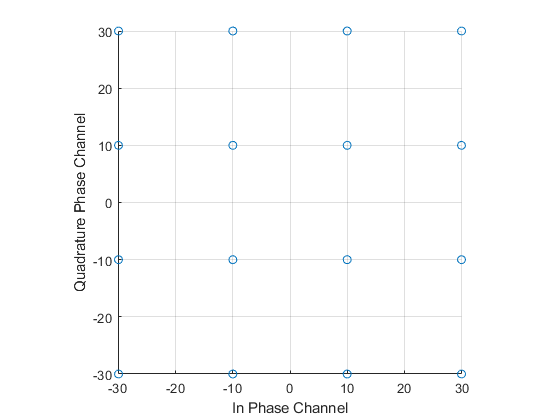

scatter(symbolsRxI, symbolsRxQ)
xlabel('In Phase Channel')
ylabel('Quadrature Phase Channel')
grid on
axis square

% [RxsI, tauI] = xcorr(symbolsI, symbolsRxI);
% plot(tauI, RxsI)
% [RxsQ, tauQ] = xcorr(symbolsQ, symbolsRxQ);
% plot(tauQ, RxsQ)

% Find Bit Error Rate

% plot(symbolsRxQ - symbolsQ)
% plot(symbolsRxI(2:end) - symbolsI(1:end-1))

% iErrors = symbolsRxI(2:end) - symbolsI(1:end-1);
iErrors = symbolsRxI - symbolsI;
iErrors = abs(iErrors)

iErrors =      0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000    20.0000e+000     0.0000e+000


iErrors(iErrors > 0.5) = 1;
iErrors(iErrors <= 0.5) = 0;

numberOfIErrors = sum(iErrors)

numberOfIErrors =      5.0000e+000


serI = numberOfIErrors/numberOfSymbols

serI =     20.0000e-003


berI = serI/log2(M)

% qErrors = symbolsRxQ(2:end) - symbolsQ(1:end-1);
qErrors = symbolsRxQ - symbolsQ;
qErrors = abs(qErrors);
qErrors(qErrors > 0.5) = 1;
qErrors(qErrors <= 0.5) = 0;


numberOfQErrors = sum(qErrors)

numberOfQErrors =      2.0000e+000


serQ = numberOfQErrors/numberOfSymbols

serQ =      8.0000e-003


berQ = serQ/log2(M)

berQ =      2.0000e-003




numberOfErrors = 0;
for k = 1:numberOfSymbols
    if symbolsRxI(k) ~= symbolsI(k) || symbolsRxQ(k) ~= symbolsQ(k)
        numberOfErrors = numberOfErrors + 1;    
    end
end
ser = numberOfErrors/numberOfSymbols;
ber = ser/log2(M);
disp('Bit Error Rates Found')

Bit Error Rates Found
